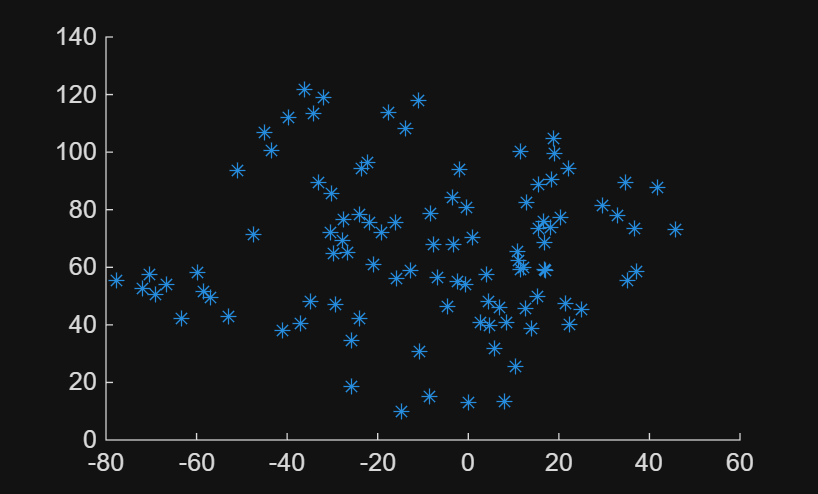

NP = 100;
Gdx = 100;
Gdy = 100;
P = rand([100 2])*100;
V = [-P(:,2) P(:,1)];
dt = .01;


PS = scatter(P(:,1),P(:,2),'*');

for i=1:100

    V = V - dt.*P;
    P = P + dt.*V;

    set(PS,'XData',P(:,1),'YData',P(:,2));
    drawnow;
end